# Sample 10-1

## 冗長変換

非間引きハールDWT

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Redundant transforms

Undecimated Haar DWT

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

## 入力信号の生成

(Generation of input)

% Input signal
u = rand(16,1); % Set to even length

### 並列フィルタバンク実装

(Parallel filter bank implementation)

分析フィルタバンクをデシメータで、合成フィルタバンクをインタポレータで実装 (Analysis filter banks are implemented with decimetors and synthesis filter banks are implemented with interpolators.)

% # of channels
nChs = 2;

% Analysis filters
h0 = [ 1  1 ]/2;
h1 = [ 1 -1 ]/2;

% Synthesis filters
f0 = [  1 1 ]/2; 
f1 = [ -1 1 ]/2;

% Analysis process
s0 = conv(h0,u);
s1 = conv(h1,u);

% Synthesis process
v0 = conv(f0,s0);
v1 = conv(f1,s1);
v = v0 + v1;

## 信号表示

(Signal display)

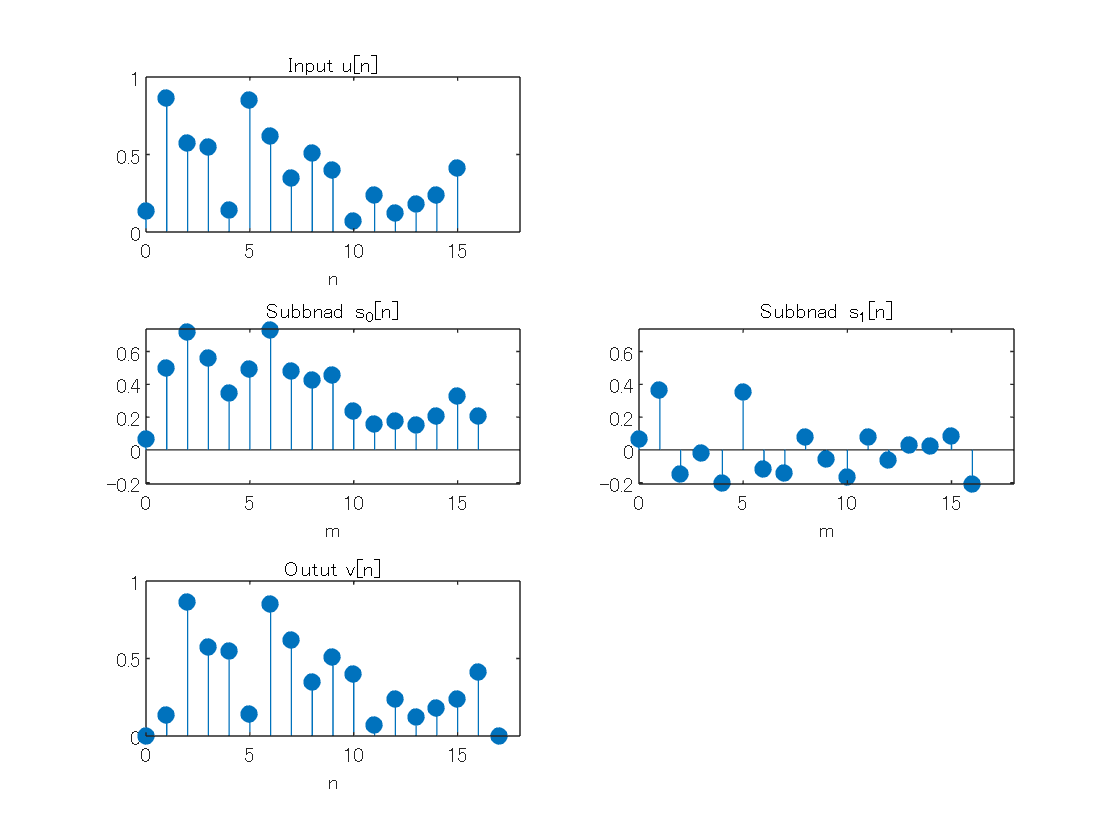

figure(1)
% Input
subplot(3,2,1)
stem(0:length(u)-1,u,'filled')
title('Input u[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];

% Subband 0
subplot(3,2,3)
stem(0:length(s0)-1,s0,'filled')
title('Subbnad s_0[n]')
xlabel('m')
ax = gca;
ax.XLim =[ 0 length(v)];
ax.YLim =[ min([s0(:);s1(:)]) max([s0(:);s1(:)]) ];

% Subband 1
subplot(3,2,4)
stem(0:length(s1)-1,s1,'filled')
title('Subbnad s_1[n]')
xlabel('m')
ax = gca;
ax.XLim =[ 0 length(v)];
ax.YLim =[ min([s0(:);s1(:)]) max([s0(:);s1(:)]) ];

% Output
subplot(3,2,5)
stem(0:length(v)-1,v,'filled')
title('Outut v[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];


% MSE 評価
mymse = @(x,y) mean((x(:)-y(:)).^2);
disp(['MSE = ', num2str(mymse(u, v(2:end-1)))]);

MSE = 1.0111e-33


### インパルス応答（基底ベクトル）

(Impluse responses of synthesis filters; basis vectors)

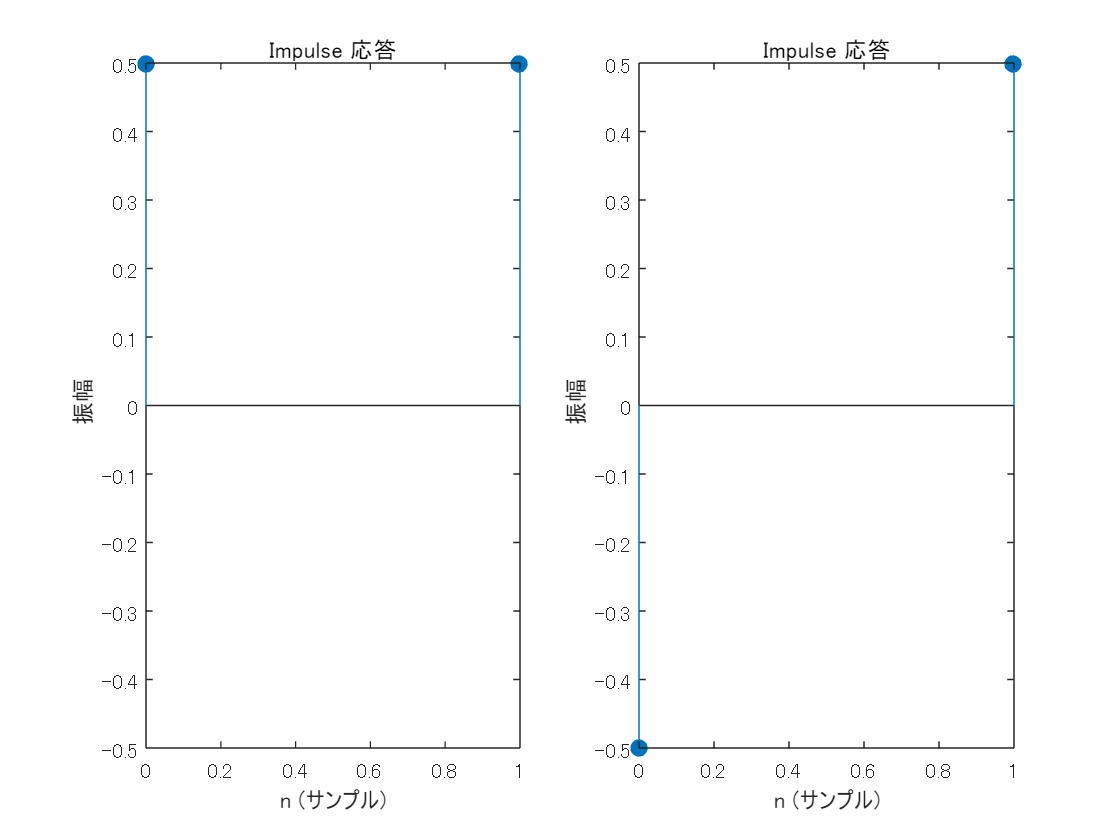

figure(2)
% Low-pass filter
subplot(1,2,1)
impz(f0)
ax = gca;
ax.YLim =[ min([f0(:);f1(:)]) max([f0(:);f1(:)]) ];

% High-pass filter
subplot(1,2,2)
impz(f1)
ax = gca;
ax.YLim =[ min([f0(:);f1(:)]) max([f0(:);f1(:)]) ];

### 周波数応答

(Frequency responses)

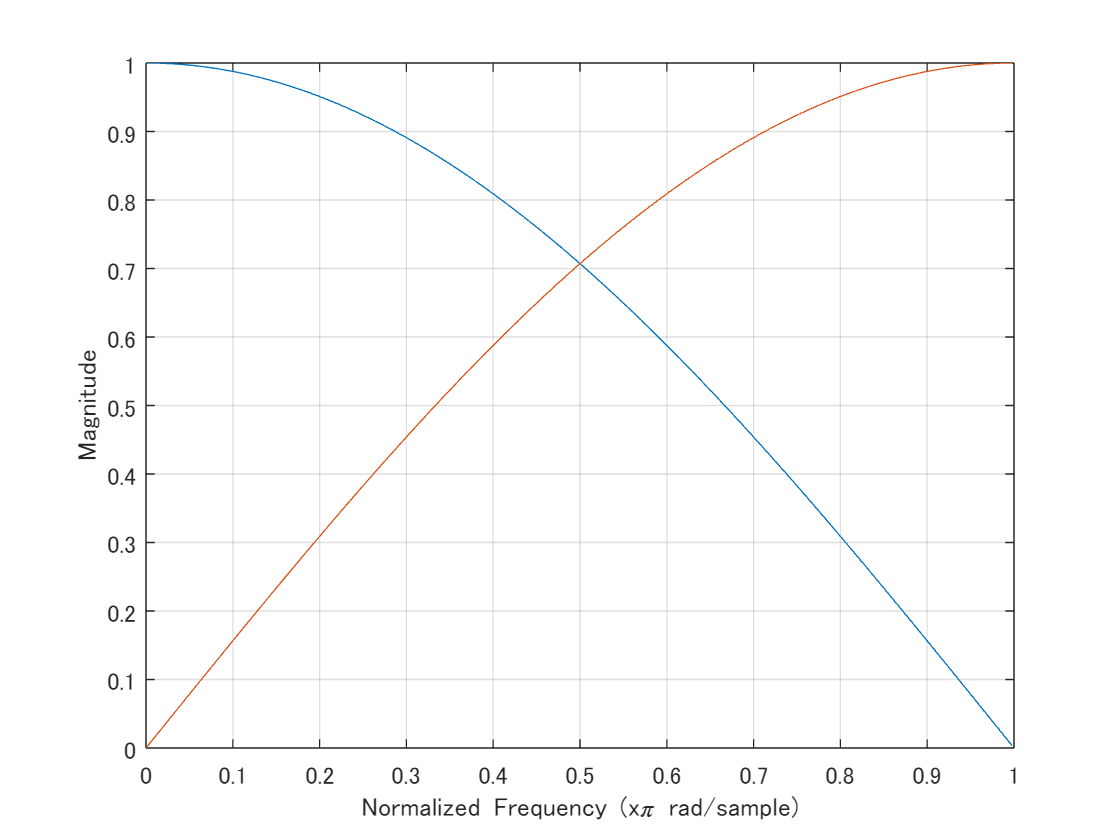

figure(3)
fftPoints = 512;
F = zeros(fftPoints,nChs);
% Low-pass filter
[F(:,1),W] = freqz(f0,1,fftPoints);
% High-pass filter
F(:,2)     = freqz(f1,1,fftPoints);
plot(W/pi,abs(F)) %20*log10(abs(F)))
axis([0 1 0 1]) %-70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude') % (dB)')
grid on

### 恒等変換

(Noble identity)

以下の性質が成り立つ。（The following properties hold.)

- 
$$\rightarrow [H(z^M)] \rightarrow [\downarrow M] \rightarrow \ \Longleftrightarrow\ \rightarrow [\downarrow M] \rightarrow  [H(z)] \rightarrow$$
 

- 
$$ \rightarrow [\uparrow M] \rightarrow  [F(z^M)] \rightarrow \ \Longleftrightarrow \ \rightarrow [F(z)] \rightarrow [\uparrow M] \rightarrow$$
 

なお， $H(z^M)$ および $F(z^M)$ は，$H(z)$ および $F(z)$ のインパルス応答 $\{h[n]\}_n$ と  $\{f[n]\}_n$をそれぞれ補間率 $M$ で零値挿入したインパルス応答をもつ。(where $H(z^M)$ and $F(z^M)$ have the impulse responses of upsampled ones of$H(z)$ and $F(z)$ with factor $M$, respectively.)

- 
$$H(z^M)=\sum_{m=-\infty}^{\infty}h[m]z^{-Mm}=\sum_{n=-\infty}^{\infty}h_{\uparrow M}[n]z^{-n}$$


- 
$$F(z^M)=\sum_{m=-\infty}^{\infty}f[m]z^{-Mm}=\sum_{n=-\infty}^{\infty}f_{\uparrow M}[n]z^{-n}$$


### 非間引き Haar DWTの実装

(Implementation of undesimated Haar DWT)

% Period for circular convolution
period = 32;

% 3-level hierachical analysis filters
h1_0 = h1;  % H0
h0_L = h0;  % L0
h1_1 = conv(h0_L,upsample(h1,2)); % H1
h0_L = conv(h0_L,upsample(h0,2)); % L1
h1_2 = conv(h0_L,upsample(h1,4)); % H2
h0_L = conv(h0_L,upsample(h0,4)); % L2
h0_2 = h0_L;

% 3-level hierachical synthesis filters
f1_0 = f1; % H0
f0_L = f0; % L0
f1_1 = conv(f0_L,upsample(f1,2)); % H1
f0_L = conv(f0_L,upsample(f0,2)); % L1
f1_2 = conv(f0_L,upsample(f1,4)); % H2
f0_L = conv(f0_L,upsample(f0,4)); % L2
f0_2 = f0_L;

% 3-level hierachical analysis process
s30 = cconv(h0_2,u,period); % L3
s31 = cconv(h1_2,u,period); % H3
s21 = cconv(h1_1,u,period); % H2
s11 = cconv(h1_0,u,period); % H1

% 3-level hierachical synthesis process
v30 = cconv(f0_2,s30,period); % L3
v31 = cconv(f1_2,s31,period); % H3
v21 = cconv(f1_1,s21,period); % H2
v11 = cconv(f1_0,s11,period); % H1
v = v30 + v31 + circshift(v21,4) + circshift(v11,6); % Delay in each channel is taken into account

## 信号表示

(Signal display)

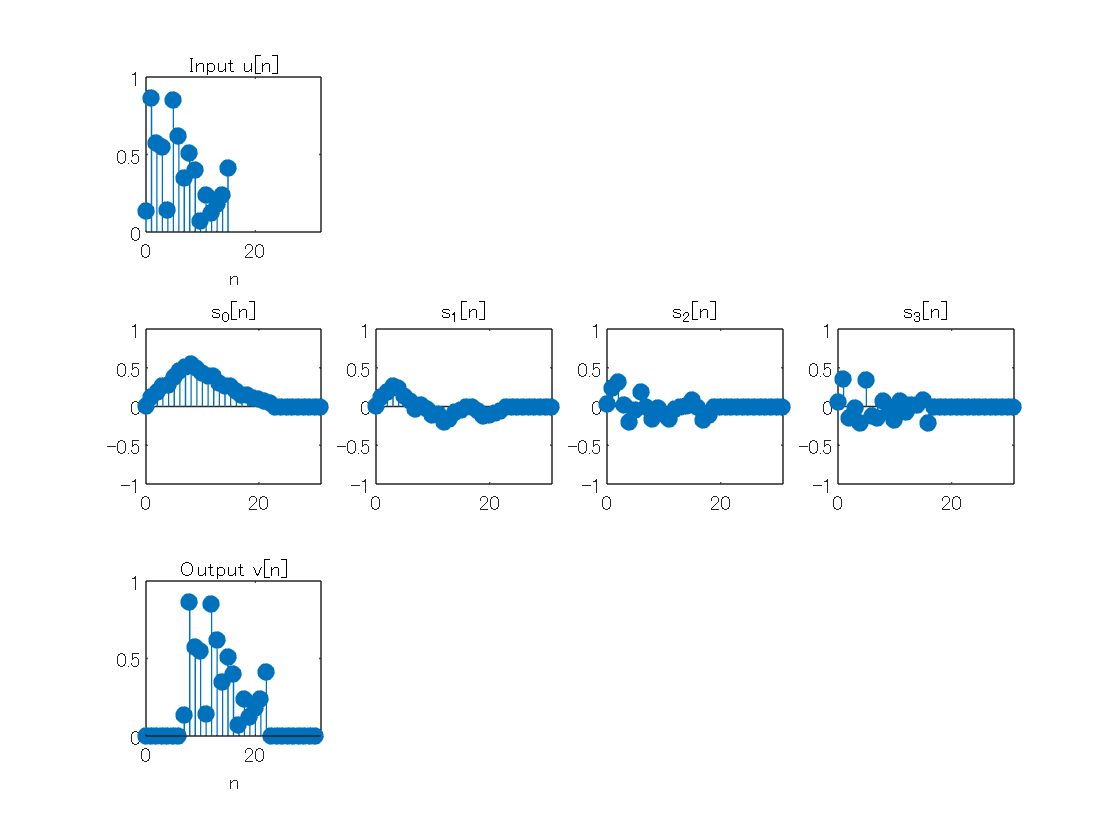

figure(4)
% Input
subplot(3,4,1)
stem(0:length(u)-1,u,'filled')
title('Input u[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 period];

% Subband 30
subplot(3,4,5)
stem(0:length(s30)-1,s30,'filled')
title('s_0[n]')
ax = gca;
ax.YLim = [ -1 1 ];

% Subband 31
subplot(3,4,6)
stem(0:length(s31)-1,s31,'filled')
title('s_1[n]')
ax = gca;
ax.YLim = [ -1 1 ];

% Subband 21
subplot(3,4,7)
stem(0:length(s21)-1,s21,'filled')
title('s_2[n]')
ax = gca;
ax.YLim = [ -1 1 ];

% Subband 11
subplot(3,4,8)
stem(0:length(s11)-1,s11,'filled')
title('s_3[n]')
ax = gca;
ax.YLim = [ -1 1 ];

% Output
subplot(3,4,9)
stem(0:length(v)-1,v,'filled')
title('Output v[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 period ];

% MSE 評価
disp(['MSE = ', num2str(mymse([u(:); zeros(length(v)-length(u),1)],circshift(v,-7)))])

MSE = 7.3784e-33


### インパルス応答（局所基底ベクトル）

(Impluse responses of synthesis filters; local basis vectors)

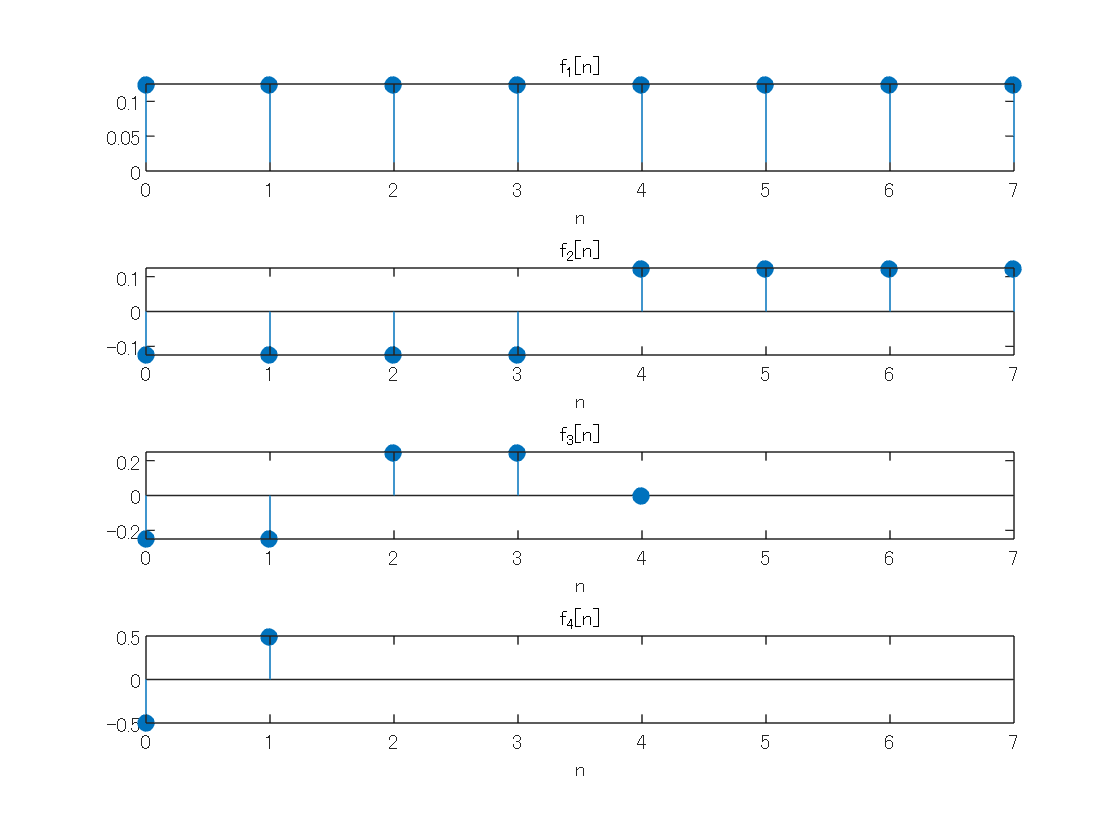

% 3-level hierachical synthesis process
figure(5)
f = cell(4,1);
f{1} = f0_2;
f{2} = f1_2;
f{3} = f1_1;
f{4} = f1_0;
for idx = 1:length(f)
    subplot(length(f),1,idx)
    stem(0:length(f{idx})-1,f{idx},'filled')
    title(['f_' num2str(idx) '[n]'])
    xlabel('n')
    ax = gca;
    ax.XLim =[0 7];
end

### 周波数応答

(Frequency responses)

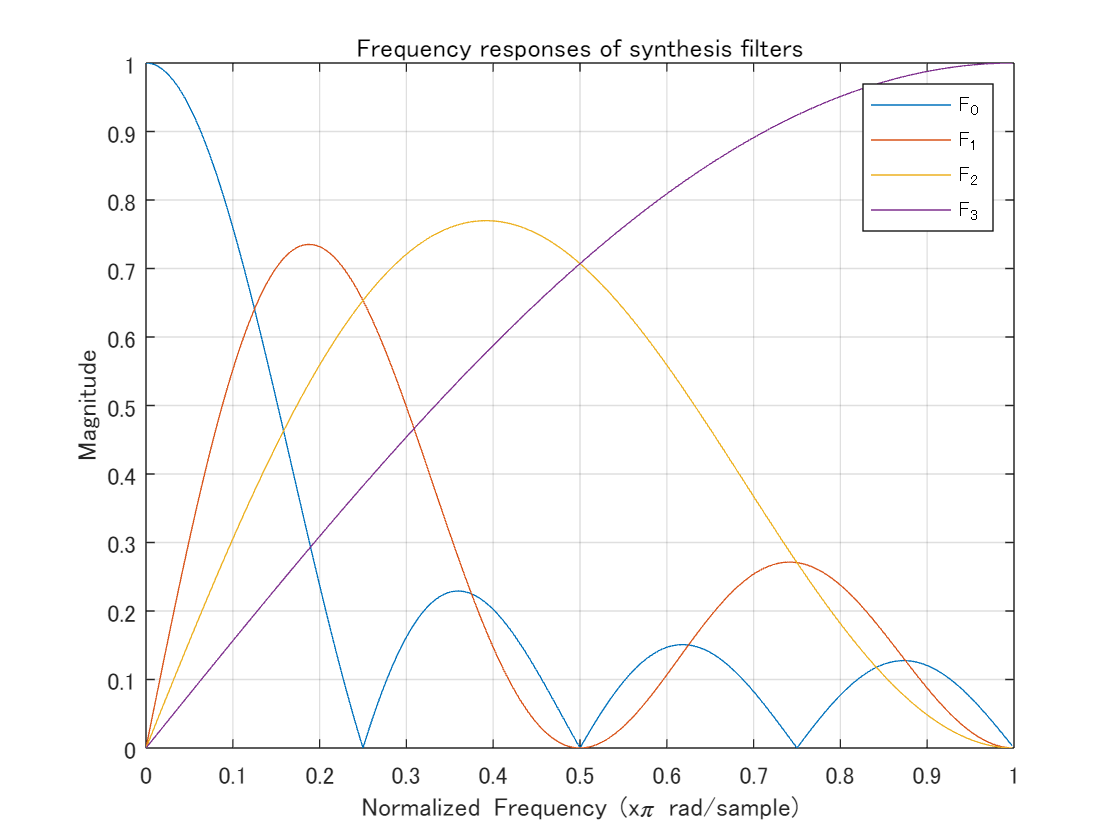

figure(6)
fftPoints = 512;
F = zeros(fftPoints,4);
for idx = 1:length(f)
    if idx == 1
        [F(:,idx),W] = freqz(f{idx},1,fftPoints);
    else
        F(:,idx)     = freqz(f{idx},1,fftPoints);
    end
end
plot(W/pi, abs(F)) %20*log10(abs(F)))
axis([0 1 0 1]) %-70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude') % (dB)')
title('Frequency responses of synthesis filters')
legend({'F_0','F_1','F_2','F_3'})
grid on

© Copyright, Shogo MURAMATSU, All rights reserved.